# Etapa 2.  Gráfica de líneas de campo magnético (2D) para un dipolo magnético.

## Datos iniciales

%Constantes
NumPuntos = 75; %Numero de cargas a graficar a través del aro
radio = 50; %Radio aro
miu = 4*pi*10^-7; %Constante de permeabildiad
I = 75; %Corriente

## Espacio

spacex = linspace(-75,75,NumPuntos); %Vector de espacio en X
spacey = linspace(-75,75,NumPuntos); %Vector de espacio en Y
[X,Y] = meshgrid(spacex,spacey); %Matriz de espacio

## Cálculo del campo

r = sqrt(X.^2 + Y.^2);
rcuadrada = r.^2;
rcubica = r.^3;
% Campo en y
CampoX1 = (miu*I*(pi*radio)^2);
CampoX2 = 3.*X.*Y;
CampoX3 = 4.*rcubica;
CampoX4 = rcuadrada;
%Campo en z
CampoY1 = (miu*I*(pi*radio)^2);
CampoY2 = 3.*(Y.^2);
CampoY3 = 4.*rcubica;
CampoY4 = rcuadrada;
%Campos totales
CampoX = (CampoX1./CampoX3).*(CampoX2./CampoX4);
CampoY = ((CampoY1./CampoY3).*((CampoY2./CampoY4)-1));
CampoTotal = sqrt(CampoX.^2 + CampoY.^2);
CampX = CampoX./CampoTotal;
CampY= CampoY./CampoTotal;

## Graficando

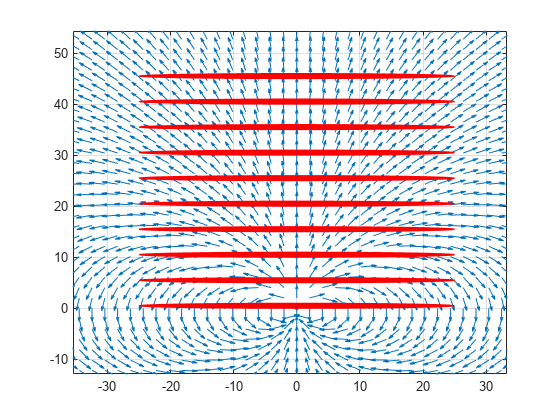

quiver(X,Y,CampX,CampY);
axis([-75 75 -75 75]);
grid on
NumEspiras = 10;
separacion = 5;
posinicial = 0;
for i=1:NumEspiras;
rectangle('Position',[-radio/2 posinicial radio 1],'Curvature',[1 1],'Facecolor',[1 0 0],'Edgecolor', [1 0 0]);
posinicial = posinicial + separacion;
end